CurrentFolder = pwd
FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
addpath([CurrentFolder '/HPCData'])

S_EEtest = [0.020 0.024 0.028];
S_IItest = [0.06  0.09  0.12  0.15  0.18];
Panel1 = length(S_EEtest); Panel2 = length(S_IItest);
S_ElgnInd = 3;
S_IlgnInd = 3;
rI_L6Ind = 3;

## All S_II slices

figure('Name','Contour')
for S_EEInd = 1:length(S_EEtest)
    S_EE = S_EEtest(S_EEInd);
    S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
    S_Elgn=S_Elgntest(S_ElgnInd);
    for S_IIInd = 1:length(S_IItest)
        S_II = S_IItest(S_IIInd);
        S_Ilgntest = [1 1.5 2 2.5]*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);
        
        load(sprintf('ContourData_S_EE=%.3f_S_II=%.2f_S_Elgn=%.3f_7D_HPC_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                  S_EE,     S_II,     S_Elgn,            S_IlgnInd,  rI_L6Ind),'ContourData_7D')
        
        subplot(Panel1, Panel2, S_IIInd+Panel2*(S_EEInd-1))
        %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,
        %rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        hold on
        CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,: ));
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: ));
        CurrentFrE(CurrentFrE<eps) = nan; CurrentFrE(CurrentBlowup == 1) = nan;
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        CurrentFrI(CurrentFrI<eps) = nan; CurrentFrI(CurrentBlowup == 1) = nan;
        [C1,h1]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
            CurrentFrE,[3  5 ],'ShowText','on','color','r');
        clabel(C1,h1,'FontSize',10,'Color','k')
        [C2,h2]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
            CurrentFrI,[8  15],'ShowText','on','color','b');
        clabel(C2,h2,'FontSize',10,'Color','k')
        hold off
        title(sprintf('S_{EE}=%.3f; S_{II}=%.2f\nS_{Elgn}=%.3f; S_{Ilgn}=%.3f',...
                       S_EE,        S_II,        S_Elgn,        S_Ilgn))
        xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
        %xlim([0.06 0.5])
    end
end

Check blowups

% figure('Name','Failure') SampleNum = ContourData_Base.SampleNum; for
% S_IlgnInd = 1:ContourData_Base.PanelNum1
%     S_Ilgn = ContourData_Base.S_Ilgntest(S_IlgnInd); for rI_L6Ind =
%     1:ContourData_Base.PanelNum2
%         rI_L6 = ContourData_Base.rI_L6test(rI_L6Ind);
%
%         load(sprintf('ContourData_S_EE=0.024_S_Elgn=%.3f_7D_HPC_PX%d_PY%d.mat',S_Elgn,S_IlgnInd,rI_L6Ind),'ContourData_7D')
%
%         subplot(ContourData_Base.PanelNum1, ContourData_Base.PanelNum2,
%         rI_L6Ind+ContourData_Base.PanelNum2*(S_IlgnInd-1))
%         %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,
%         rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1)) CurrentBlowup =
%         squeeze(ContourData_7D.FailIndi(:,: ));
%
%
%
%         imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,CurrentBlowup);
%
%         S_Ilgntxt = sprintf('%.3f',S_Ilgn); rI_L6txt =
%         sprintf('%.3f',rI_L6); title(['S_{Ilgn} = ' S_Ilgntxt ', rI_{L6}
%         = ' rI_L6txt ]) xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as
%         y*S_{EE}') set(gca,'Ydir','Normal') %xlim([0.06 0.5])
%     end
% end


## Firing rate heapmap

figure('Name','Ratemap')
for S_EEInd = 1:length(S_EEtest)
    S_EE = S_EEtest(S_EEInd);
    S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
    S_Elgn=S_Elgntest(S_ElgnInd);
    for S_IIInd = 1:length(S_IItest)
        S_II = S_IItest(S_IIInd);
        S_Ilgntest = [1 1.5 2 2.5]*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);
        
        load(sprintf('ContourData_S_EE=%.3f_S_II=%.2f_S_Elgn=%.3f_7D_HPC_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                  S_EE,     S_II,     S_Elgn,            S_IlgnInd,  rI_L6Ind),'ContourData_7D')
        
        subplot(Panel1*2, Panel2, S_IIInd+Panel2*(S_EEInd-1))
        hold on
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); CurrentFrE(CurrentFrE<eps) = nan;
        imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, CurrentFrE)
        set(gca,'YDir','normal')
        colormap("jet"); colorbar; caxis([0 15])
        
        [C1,h1]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                         CurrentFrE,[3  5 ],'ShowText','on','color','r');
        clabel(C1,h1,'FontSize',10,'Color','k')
        hold off
        title(sprintf('S_{EE}=%.3f; S_{II}=%.2f\nS_{Elgn}=%.3f; S_{Ilgn}=%.3f',...
                       S_EE,        S_II,        S_Elgn,        S_Ilgn))
        xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
        
        subplot(Panel1*2, Panel2, S_IIInd+Panel2*(S_EEInd-1)+Panel1*Panel2)
        %     subplot(ContourData_7D.PanelNum2*2, ContourData_7D.PanelNum1,
        %     rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1)+...
        %                                                                    
        %                                                                    ContourData_7D.PanelNum2
        %                                                                    *
        %                                                                    ContourData_7D.PanelNum1)
        hold on
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: )); CurrentFrI(CurrentFrI<eps) = nan;
        imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, CurrentFrI)
        set(gca,'YDir','normal')
        colormap("jet"); colorbar; caxis([0 40])
        [C2,h2]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
            CurrentFrI,[10 18],'ShowText','on','color','k');
        clabel(C2,h2,'FontSize',10,'Color','k')
        hold off
        xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
        %xlim([0.06 0.5])
    end
end

white frE = [3 5], frI/frE = (3, 4.25)

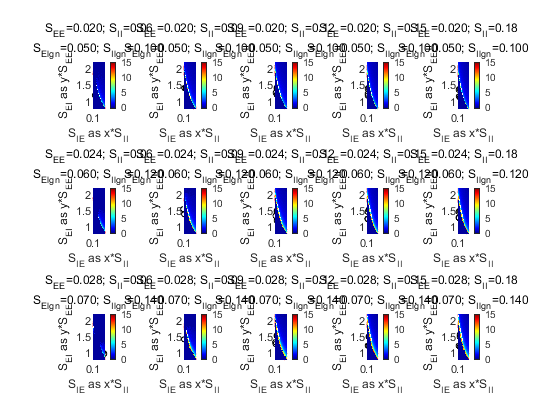

figure('Name','WhitenHeatmap')
for S_EEInd = 1:length(S_EEtest)
    S_EE = S_EEtest(S_EEInd);
    S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
    S_Elgn=S_Elgntest(S_ElgnInd);
    for S_IIInd = 1:length(S_IItest)
        S_II = S_IItest(S_IIInd);
        S_Ilgntest = [1 1.5 2 2.5]*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);
        
        load(sprintf('ContourData_S_EE=%.3f_S_II=%.2f_S_Elgn=%.3f_7D_HPC_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                  S_EE,     S_II,     S_Elgn,            S_IlgnInd,  rI_L6Ind),'ContourData_7D')
        
        subplot(Panel1, Panel2, S_IIInd+Panel2*(S_EEInd-1))
        %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,
        %rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        hold on
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %CurrentFrE(CurrentFrE<eps) = nan;
        CurrentFrE(CurrentFrE<=0) = 0;
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,: ));
        [C1,h1]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
            CurrentFrE,[3  5 ],'ShowText','on','color','r');
        clabel(C1,h1,'FontSize',10,'Color','k')
        
        CurrentFrE(CurrentFrE>=3 & CurrentFrE<=5 & ...
            CurrentFrI./CurrentFrE    >=3 & ...
            CurrentFrI./CurrentFrE    <=4.25) = nan;
        CurrentFrE(CurrentBlowup == 1) = 0;
        imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, CurrentFrE)
        set(gca,'YDir','normal')
        cmap = [1,1,1; jet];
        
        colormap(cmap); colorbar; caxis([-0.5 15])
        hold off
        title(sprintf('S_{EE}=%.3f; S_{II}=%.2f\nS_{Elgn}=%.3f; S_{Ilgn}=%.3f',...
                       S_EE,        S_II,        S_Elgn,        S_Ilgn))
        xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
    end
end

And frI/frE

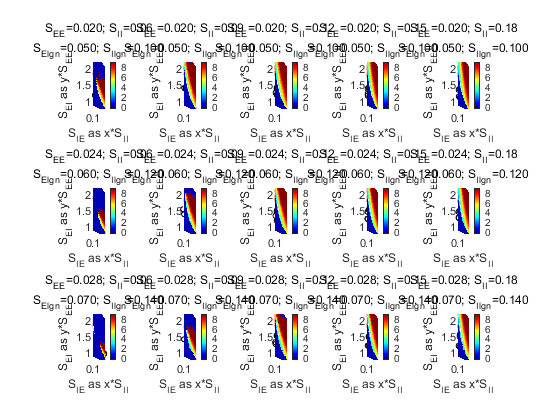

figure('Name','Fr Prop')
for S_EEInd = 1:length(S_EEtest)
    S_EE = S_EEtest(S_EEInd);
    S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
    S_Elgn=S_Elgntest(S_ElgnInd);
    for S_IIInd = 1:length(S_IItest)
        S_II = S_IItest(S_IIInd);
        S_Ilgntest = [1 1.5 2 2.5]*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);
        
        load(sprintf('ContourData_S_EE=%.3f_S_II=%.2f_S_Elgn=%.3f_7D_HPC_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                  S_EE,     S_II,     S_Elgn,            S_IlgnInd,  rI_L6Ind),'ContourData_7D')
        
        subplot(Panel1, Panel2, S_IIInd+Panel2*(S_EEInd-1))
        %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,
        %rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        hold on
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %CurrentFrE(CurrentFrE<eps) = nan;
        CurrentFrE(CurrentFrE<=0) = 0;
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,: ));
        [C1,h1]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
            CurrentFrE,[3  5 ],'ShowText','on','color','r');
        clabel(C1,h1,'FontSize',10,'Color','k')
        
        Prop = CurrentFrI./CurrentFrE;
        Prop(CurrentFrE>=3 & CurrentFrE<=5 & ...
            CurrentFrI./CurrentFrE    >=3 & ...
            CurrentFrI./CurrentFrE    <=4.25) = nan;
        Prop(CurrentBlowup == 1) = 0;
        imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, Prop)
        set(gca,'YDir','normal')
        cmap = [1,1,1; jet];
        
        colormap(cmap); colorbar; caxis([-0.5 9])
        
        
        hold off
        title(sprintf('S_{EE}=%.3f; S_{II}=%.2f\nS_{Elgn}=%.3f; S_{Ilgn}=%.3f',...
                       S_EE,        S_II,        S_Elgn,        S_Ilgn))
        xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
    end
end

## parameters

sprintf(['S_EE = %.3f, S_II = %.3f, S_Elgn = %.3f, S_amb = %.3f, S_EL6 = %.3f, S_IL6 = %.3f\n',...
    'r_Elgn = %.3f, r_Ilgn = %.3f, r_Eamb = %.3f, r_Iamb = %.3f, r_EL6 = %.3f'],...
    ContourData_7D.S_EE, ContourData_7D.S_II, ContourData_7D.S_Elgn, ContourData_7D.S_amb, ContourData_7D.S_EL6, ContourData_7D.S_IL6,...
    ContourData_7D.lambda_E, ContourData_7D.lambda_I, ContourData_7D.rE_amb, ContourData_7D.rI_amb, ContourData_7D.rE_L6)
